clear;
clc;

addpath('../funcs');
figpath = '../../report/figures/';
load ../../data/PC_power_integral_0.24_0.3_0.027_0.027_Iattn_0.02.mat;

pops = ["1L2/3E","1L2/3I","1L4E","1L4I","1L5E","1L5I","1L6E","1L6I"];
conds = ["original", "S1", "S2", "S1S2", "S1S2+A1", "S1S2+A2"];

Iattn = 0.02;
ratio_sens_attn = 3; % linspace(0.5,5,20) % fix at 9000/3000 = 3
Isens =  Iattn*ratio_sens_attn;

ratio_barE_attn = 16/3; % linspace(0.5,5,20) % fix at 16/3=5.33
I_bare = Iattn*ratio_barE_attn; % 3
ratioEi_Ibar = 1600/2000; % fix at 1600/2000 = 0.8
I_bari = I_bare*ratioEi_Ibar;

ratioEi_Isens = 0.0619/0.0983; % 0.0619/0.0983
I_sensPre = [Isens;Isens*ratioEi_Isens]; % [E;I][6;3]
I_sensNot = 0.1*I_sensPre; % 0.01
I_sensBoth = 1.1*I_sensPre; % 0.6

ratioEi_Iattn = 0.085/0.1; % 0.085/0.1
I_attn = [Iattn;Iattn*ratioEi_Iattn]; % renormalize to [0,1]

I_bar = repmat([I_bare, I_bari, I_bare, I_bari, I_bare, I_bari, I_bare, I_bari],[1,2])'; % E, I % input current % assigned by sugino
I_bar = repmat(I_bar,[1,1,5]);
step_all = 4000/0.01;
step_stimIn = 1000/0.01;
step_stimOut = 0;
step_stim = 3000/0.01;

I_bar_ext(:,:,1) = [zeros(2,step_all); zeros(2,step_stimIn),I_sensPre*ones(1,step_stim),zeros(2,step_stimOut); % 1L2/3e 1L2/3i; 1L4e 1L4i;
                 zeros(2,step_all); zeros(2,step_all); % 1L5e 1L5i; 1L6e 1L6i;
                 zeros(2,step_all); zeros(2,step_stimIn),I_sensNot*ones(1,step_stim),zeros(2,step_stimOut); % 2L2/3e 2L2/3i; 2L4e 2L4i;
                 zeros(2,step_all); zeros(2,step_all)]; % 2L5e 2L5i; 2L6e 2L6i;

% elseif condition == 2
I_bar_ext(:,:,2) = [zeros(2,step_all); zeros(2,step_stimIn),I_sensNot*ones(1,step_stim),zeros(2,step_stimOut); % 1L2/3e 1L2/3i; 1L4e 1L4i;
                 zeros(2,step_all); zeros(2,step_all); % 1L5e 1L5i; 1L6e 1L6i;
                 zeros(2,step_all); zeros(2,step_stimIn),I_sensPre*ones(1,step_stim),zeros(2,step_stimOut); % 2L2/3e 2L2/3i; 2L4e 2L4i;
                 zeros(2,step_all); zeros(2,step_all)]; % 2L5e 2L5i; 2L6e 2L6i;

% elseif condition == 3
I_bar_ext(:,:,3) = [zeros(2,step_all); zeros(2,step_stimIn),I_sensBoth*ones(1,step_stim),zeros(2,step_stimOut); % 1L2/3e 1L2/3i; 1L4e 1L4i;
                 zeros(2,step_all); zeros(2,step_all); % 1L5e 1L5i; 1L6e 1L6i;
                 zeros(2,step_all); zeros(2,step_stimIn),I_sensBoth*ones(1,step_stim),zeros(2,step_stimOut); % 2L2/3e 2L2/3i; 2L4e 2L4i;
                 zeros(2,step_all); zeros(2,step_all);]; % 2L5e 2L5i; 2L6e 2L6i;

% elseif condition == 4
I_bar_ext(:,:,4) = [zeros(2,step_stimIn),I_attn*ones(1,step_stim),zeros(2,step_stimOut); % 1L2/3e 1L2/3i;
                 zeros(2,step_stimIn),I_sensBoth*ones(1,step_stim),zeros(2,step_stimOut); % 1L4e 1L4i;
                 zeros(2,step_stimIn),I_attn*ones(1,step_stim),zeros(2,step_stimOut); % 1L5e 1L5i;
                 zeros(2,step_all); % 1L6e 1L6i;
                 zeros(2,step_all); zeros(2,step_stimIn),I_sensBoth*ones(1,step_stim),zeros(2,step_stimOut); % 2L2/3e 2L2/3i; 2L4e 2L4i;
                 zeros(2,step_all); zeros(2,step_all)]; % 2L5e 2L5i; 2L6e 2L6i

% elseif condition == 5
I_bar_ext(:,:,5) = [zeros(2,step_all); zeros(2,step_stimIn),I_sensBoth*ones(1,step_stim),zeros(2,step_stimOut); % 1L2/3e 1L2/3i; 1L4e 1L4i;
                 zeros(2,step_all); zeros(2,step_all); % 1L5e 1L5i; 1L6e 1L6i;
                 zeros(2,step_stimIn),I_attn*ones(1,step_stim),zeros(2,step_stimOut); % 2L2/3e 2L2/3i;
                 zeros(2,step_stimIn),I_sensBoth*ones(1,step_stim),zeros(2,step_stimOut); % 2L4e 2L4i;
                 zeros(2,step_stimIn),I_attn*ones(1,step_stim),zeros(2,step_stimOut); % 2L5e 2L5i;
                 zeros(2,step_all)]; % 2L6e 2L6i;

I_back = squeeze(I_bar);
I_back = [I_back I_back(:,1)];
I_ext = squeeze(I_bar_ext(:,300000,:));
I_ext = [zeros(16,1) I_ext];
N = [10341 2917 10957 2739 2425 532 7197 1474 10341 2917 10957 2739 2425 532 7197 1474]';
clear I_bar I_bar_ext

integral_t = 5; % 5 s

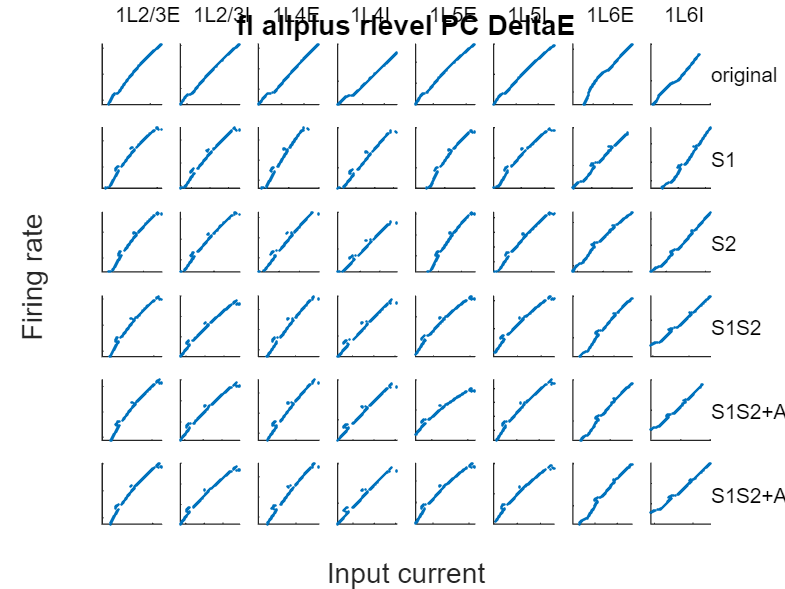

fig = figure;
fig_title = 'fI allplus rlevel PC DeltaE';
for pop = 1:8
for cond = 1:6 % 1-original 2-S1 ...

subfig = pop + (cond-1)*8;
firing_rate = squeeze(finalR(:,pop,cond));
% firing_rate = squeeze(powerR(:,pop,cond));
% firing_rate = squeeze(centerfreqR(:,pop,cond));
% firing_rate = squeeze(integralR(:,pop,cond));
% firing_rate = squeeze(powerIntR(:,pop,cond));
pathways = squeeze(PC(:,pop,1:16,:));
I_all = zeros(size(firing_rate,1),1);

for i = 1:16
    % I_all = I_all + (-1)^(i-1) * pathways(:,i,cond);
    I_all = I_all + pathways(:,i,cond);
end

I_all = I_all + integral_t*N(pop)*(I_back(pop,cond) + I_ext(pop,cond));

subplot(6,8,subfig);
scatter(I_all,firing_rate,1,'filled');
% axis off;
set(gca,'xticklabel',[])
set(gca,'yticklabel',[])
end
end

for i = 1:length(pops)
    annotation('textbox', [0.13+(i-1)/10, 0.94, 0.125, 0.07], 'String', pops(i),...
        'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 8);
end

for i = 1:length(conds)
    annotation('textbox', [0.89, 0.95-(i/7), 0.05, 0.1], 'String', conds(i),...
        'FitBoxToText', 'on', 'EdgeColor', 'none', 'FontSize', 8);
end

% Give common xlabel, ylabel and title to your figure
han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Firing rate');
xlabel(han,'Input current');
title(han,fig_title);

% xlabel('Input current');
% ylabel('Firing rate');

set(gca, 'FontName', 'Arial');
filename = append(figpath,fig_title);
print(filename, '-dpng', '-r600');